# Transverse-Shear Locking in Shear-Deformable Plates `-` Two Sided Clampled Plate Subject to Vertical Distributed Load

## Introduction

This chapter investigates the transverse-shear locking that is exhibited by the low-order Finite Element discretizations of the [Reissner-Mindlin plate](https://en.wikipedia.org/wiki/Mindlin%E2%80%93Reissner_plate_theory) for the setup of a square plate subject to vertical distributed force $\bar{p}$ while it is clamped along two of its edges, see the following figure:

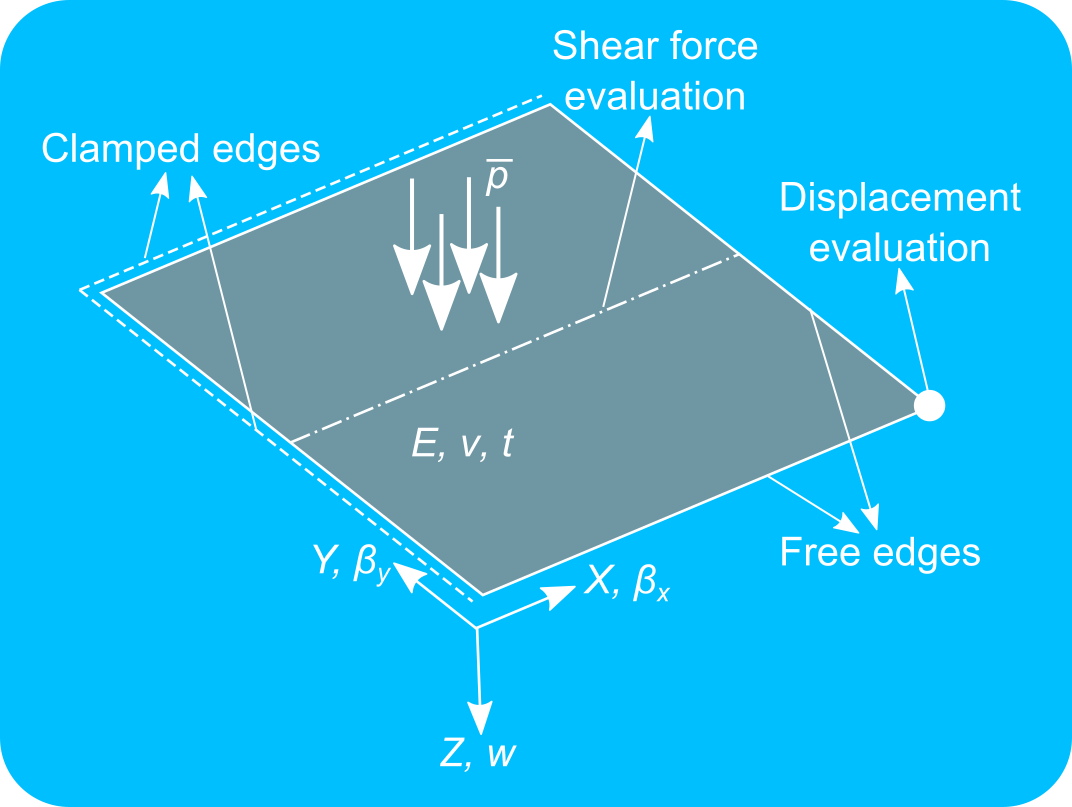

For this problem there is no known analytical solution in terms of the vertical deflection and the cross-sectional rotation fields. As a reference solution it is used the precomputed solution of the same problem using the Kirchhoff plate theory. It is known that for thin plates both the Reissner-Mindlin and Kirchhoff theories should deliver very similar results. However, this should not be the the case for moderetely thick or thick plates. This is demonstrated in this Live Script.

The Assumed Natural Strain (ANS) method is herein used to alleviate locking. The method entails resampling the strain field at additional evaluation points within each element while assuming a "natural" form of the strain components in the element level before computing the discrete quantities as in the usual case.

Two types of discretizations are considered herein: A bilinear and a biquadratic quadrilateral discretization. It is first shown the distribution of the transverse shear forces $q_x$ along the diagonal line shown above and it is highlighted the spurious transverse shear forces, especially for the low-order discretization.

Subsequently the vertical deflection of the plate at its tip is investigated with respect to the slenderness $L/t$. In this way it is shown, how the spurious transverse shear forces dominate the solution when the bilinear quadrilateral elements are used leading to an ever-decreasing vertical deflection with increasing slenderness.

Finally a convergence study is performed demonstrating the resulting prohibitly slow convergence of the low-order elements attributed to the transverse shear locking.

[PREVIOUS Chapter](matlab:open('..\4_TransverseShearLocking_ReissnerMindlinCantileverPlate\main_Chapter4_Locking_ReissnerMindlinCantileverPlate.mlx')) *Transverse Shear Locking in Shear-Deformable Plates *`-`* Cantilever Plate Subject to Vertical Distributed Load*

[NEXT Chapter](matlab:open('..\..\5_WeakDirichletBoundaryConditions\main_Chapter5_WeakBoundaryConditions_TimoshenkoBeam.mlx')) *Weak Imposition of Dirichlet Boundary Conditions for the Timoshenko Beam Boundary Value Problem*

**Author: Andreas Apostolatos, PhD (aapostol@mathworks.com)**

**Date: 20.02.2023**

## Preamble

clc;
clear;
close all;

## **Problem setup**

### Geometric parameters

Thickness [m]

propStr.t = 10^(-1);

X-coordinate of left corner [m]

X0 = 0;

X-coordinate of right corner [m]

XLx = 4;

Y-coordinate of left corner [m]

Y0 = 0;

Y-coordinate of right corner [m]

YLy = XLx;

### Material paramerters

Distributed load [N/m^2]

propStr.pBar = -4e4*(propStr.t)^3;

Distributed moment around x-axis [N/m]

propStr.mxBar = 0;

Distributed moment around y-axis [N/m]

propStr.myBar = 0;

Young's modulus [N/m^2]

propStr.E = 1e7;

Poisson ratio [dimensionless]

propStr.nu = 0.3;

Shear modulus (connected to epsilon_12 = E/(1+nu)) [N/m^2]

propStr.G = propStr.E/2/(1 + propStr.nu);

Plate's stiffness [Nm]

propStr.D = propStr.E*propStr.t^3/12/(1 - propStr.nu^2);

Shear-correction factor

propStr.alpha = 5/6;

### Newton-Raphson properties for the inversion of the geometry map

Convergence tolerance

propNewtonRaphson.eps = 1e-9;

Maximum number of iterations

propNewtonRaphson.maxIt = 10;

## Definition of the analytical expressions for the two-dimensional basis functions

### Define the analytical expressions for the bilinear basis functions


$$N_1^{Q_1}(\xi, \eta) = \frac{1}{4}(1 - \xi)(1 - \eta) \quad (\xi,\eta) \in [0, 1], \quad (1.1) \\
N_2^{Q_1}(\xi, \eta) = \frac{1}{4}(1 + \xi)(1 - \eta) \quad (\xi,\eta) \in [0, 1], \quad (1.2) \\
N_3^{Q_1}(\xi, \eta) = \frac{1}{4}(1 + \xi)(1 + \eta) \quad (\xi,\eta) \in [0, 1], \quad (1.3) \\
N_4^{Q_1}(\xi, \eta) = \frac{1}{4}(1 - \xi)(1 + \eta) \quad (\xi,\eta) \in [0, 1]. \quad (1.4)$$


syms N1Q1(xi, eta) N2Q1(xi, eta) N3Q1(xi, eta) N4Q1(xi, eta)
N1Q1(xi, eta) = (1 - xi)*(1 - eta)/4;
N2Q1(xi, eta) = (1 + xi)*(1 - eta)/4;
N3Q1(xi, eta) = (1 + xi)*(1 + eta)/4;
N4Q1(xi, eta) = (1 - xi)*(1 + eta)/4;
N_Q1 = [N1Q1 N4Q1 N3Q1 N2Q1];

### Define the analytical expressions for the biquadratic basis functions


$$N_1^{Q_2}(\xi, \eta) = \frac{1}{4} \xi (\xi - 1) \eta (1 - \eta) \quad (\xi,\eta) \in [0, 1], \quad \quad \quad \quad \quad (2.1)  \\
N_2^{Q_2}(\xi, \eta) = -\frac{1}{2}(\xi + 1)(\xi - 1)\eta(\eta - 1) \quad (\xi,\eta) \in [0, 1], \quad \; \; \, (2.2) \\
N_3^{Q_2}(\xi, \eta) = \frac{1}{4}(\xi + 1)\xi \eta(\eta - 1) \quad (\xi,\eta) \in [0, 1], \quad \quad \quad \quad \quad (2.3) \\
N_4^{Q_2}(\xi, \eta) = -\frac{1}{2}(\xi + 1)\xi(\eta + 1)(\eta - 1) \quad (\xi,\eta) \in [0, 1], \quad \; \; \, (2.4) \\
N_5^{Q_2}(\xi, \eta) = \frac{1}{4}(\xi + 1)\xi(\eta + 1)\eta \quad (\xi,\eta) \in [0, 1], \quad \quad \quad \quad \quad (2.5) \\
N_6^{Q_2}(\xi, \eta) = -\frac{1}{2}(\xi + 1)(\xi - 1)(\eta + 1)\eta \quad (\xi,\eta) \in [0, 1], \quad \; \; \, (2.6) \\
N_7^{Q_2}(\xi, \eta) = \frac{1}{4}\xi (\xi - 1)(\eta + 1)\eta \quad (\xi,\eta) \in [0, 1],  \quad \quad \quad \quad \quad (2.7) \\
N_8^{Q_2}(\xi, \eta) = -\frac{1}{2}\xi (\xi - 1)(\eta + 1)(\eta - 1) \quad (\xi,\eta) \in [0, 1], \quad \; \; \, (2.8) \\
N_9^{Q_2}(\xi, \eta) = \frac{1}{1}(1 - \xi^2) (1 - eta^2) \quad (\xi,\eta) \in [0, 1], 
 \quad\ \quad \quad \quad (2.9)\\$$


syms N1Q2(xi, eta) N2Q2(xi, eta) N3Q2(xi, eta) N4Q2(xi, eta) ...
    N5Q2(xi, eta) N6Q2(xi, eta) N7Q2(xi, eta) N8Q2(xi, eta) ...
    N9Q2(xi, eta)
N1Q2(xi, eta) = xi*(xi - 1)*eta*(eta - 1)/4;
N2Q2(xi, eta) = (xi + 1)*(xi - 1)*eta*(eta - 1)/-2;
N3Q2(xi, eta) = (xi + 1)*xi*eta*(eta - 1)/4;
N4Q2(xi, eta) = (xi + 1)*xi*(eta + 1)*(eta - 1)/-2;
N5Q2(xi, eta) = (xi + 1)*xi*(eta + 1)*eta/4;
N6Q2(xi, eta) = (xi + 1)*(xi - 1)*(eta + 1)*eta/-2;
N7Q2(xi, eta) = xi*(xi - 1)*(eta + 1)*eta/4;
N8Q2(xi, eta) = xi*(xi - 1)*(eta + 1)*(eta - 1)/-2;
N9Q2(xi, eta) = (xi + 1)*(xi - 1)*(eta + 1)*(eta - 1)/1;
N_Q2 = [N1Q2 N7Q2 N5Q2 N3Q2 N8Q2 N4Q2 N2Q2 N6Q2 N9Q2];

 **Reflect**

How can the setup of these interpolatory basis functions be generalized?

## **Discretization**

Both the vertical deflection $w$ and cross-sectional rotation $\beta_x$, $\beta_y$ fields are discretized using the same basis (shape) functions, namely:


$$\begin{array}{l}
w\left(\xi ,\eta \right)\approx \sum_{i=1:N} N_i \left(\xi ,\eta \right)\;w_i ,\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(3\ldotp 1\right)\\
\beta_x \left(\xi ,\eta \right)\approx \sum_{i=1:N} N_i \left(\xi ,\eta \right)\;\beta_{x,i} \;\ldotp \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(3\ldotp 2\right)\\
\beta_y \left(\xi ,\eta \right)\approx \sum_{i=1:N} N_i \left(\xi ,\eta \right)\;\beta_{y,i} \;\ldotp \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(3\ldotp 3\right)
\end{array}$$


Here $N$ indicates the total number of nodes in the mesh. Moreover a Buvnov-Galerkin discretization is used, meaning that both the test and the unknown fields are discretized using the same basis (shape) functions.

### **Quadrilateral mesh**

#### Choose number of elements in the mesh

Number of elements along the X-direction

numElx = 5;

Number of elements along the Y-direction

numEly = 5;

Total number of elements

numEl = numElx*numEly;

#### Mesh generation of quadrilateral elements

[nodesX, nodesY] = ...
    generateQuadrilateralMesh(X0, XLx, Y0, YLy, numElx, numEly);

### **Four-noded bilinear quadrilateral mesh**

#### Mesh generation

numNodesElQ1 = 4;
mshQ1 = generateBilinearQuadrilateralMesh ...
    (numElx, numEly, numEl, nodesX, nodesY, numNodesElQ1);
numNodes_Q1 = numel(mshQ1.nodes(:, 1));

#### Set-up of the Dirichlet boundary conditions

numDOFsQ1 = 3*numNodes_Q1;
[freeDOFsQ1, homDOFsQ1, idxX, homDOFsQ1X] = ...
    utilityFunctionsTwoSidedClampedPlate.getFreeDOFsBilinearQuadrilateralMesh ...
    (numNodes_Q1, numElx, numEly);

#### Mesh plot

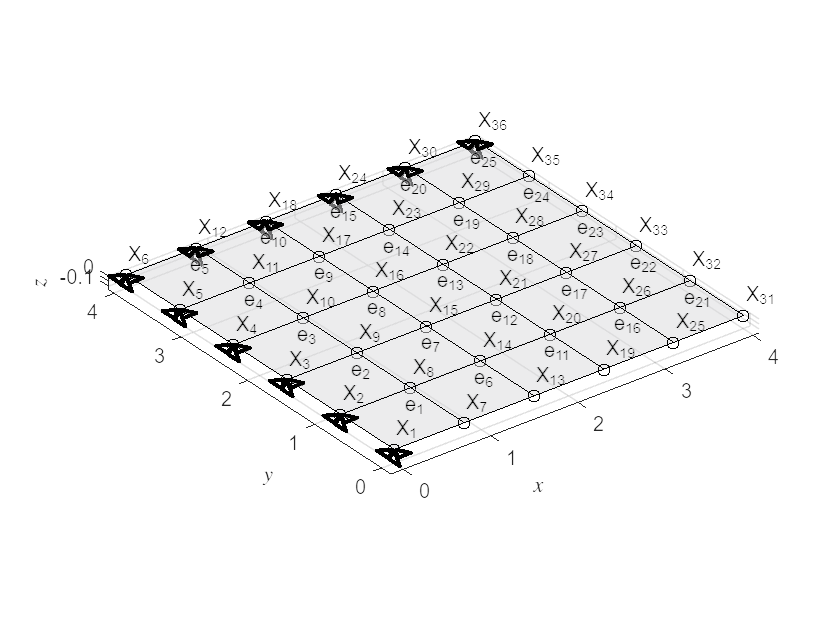

numVertices = numel(mshQ1.nodes(:, 1));
plotMesh2d(mshQ1, numVertices, true);
hold on;
scalVer = 1;
[xsQ1, ysQ1, zsQ1] = createSupports3D(mshQ1.nodes, homDOFsQ1, scalVer);
for k = 1:length(xsQ1(:, 1))
    plot3(xsQ1(k, :), ysQ1(k, :), zsQ1(k, :), 'Linewidth', 2, ...
        'Color', 'black');
end
hold off;
axis equal;
xlabel("$x$", Interpreter="latex")
ylabel("$y$", Interpreter="latex")
zlabel("$z$", Interpreter="latex")

#### Display the mesh with the basis functions

isPlotBasisFunctions = false;
if isPlotBasisFunctions
    syms xi eta
    NQ1Vis = {(1 - xi)*(1 - eta)/4, (1 - xi)*(1 + eta)/4, ...
        (1 + xi)*(1 + eta)/4, (1 + xi)*(1 - eta)/4};
    [h5, h6, h7] = plotMeshAndBasisFunctions2d(mshQ1, NQ1Vis, true);
end

  **Try**

Select the checkbox in this code section to create an animation for the bilinear basis functions throughout the mesh. Be aware that this code section can take very long to run due to rendering of complex graphics.

 **Reflect**

What is the support of the bilinear basis functions, namely, the area over which they are not identical zero?

### **Biquadratic quadrilateral mesh**

#### Mesh generation

numNodesElQ2 = 9;
[mshQ2, biasX] = generateBiquadraticQuadrilateralMesh ...
    (numElx, numEly, nodesX, nodesY, mshQ1, numNodesElQ1, numNodesElQ2);

#### Set-up of the Dirichlet boundary conditions

numNodesQ2 = numel(mshQ2.nodes(:, 1));
numDOFsQ2 = 3*numNodesQ2;
[freeDOFsQ2, homDOFsQ2] = ...
    utilityFunctionsTwoSidedClampedPlate.getFreeDOFsBiquadraticQuadrilateralMesh ...
    (numNodes_Q1, numNodesQ2, numEly, homDOFsQ1X, idxX, biasX);

#### Mesh plot

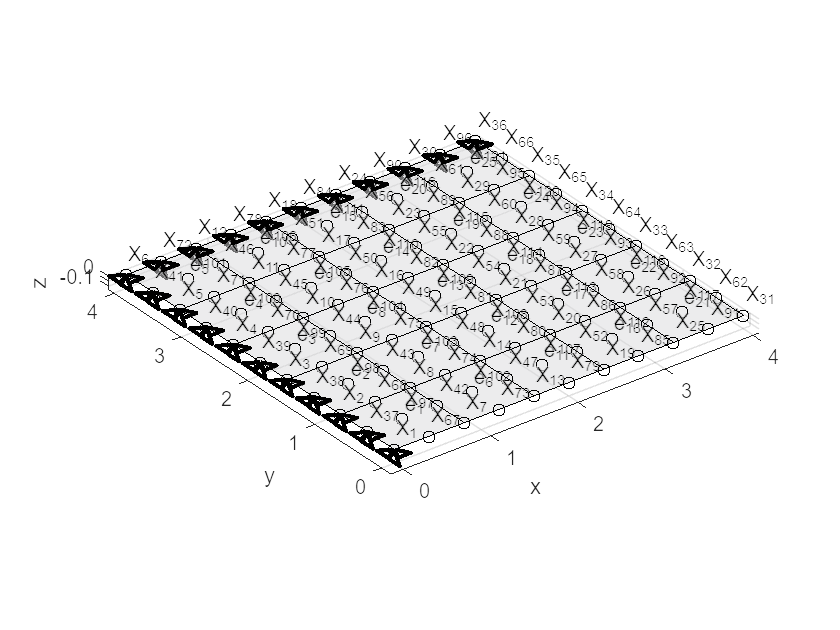

numVertices = numel(mshQ1.nodes(:, 1));
plotMesh2d(mshQ2, numVertices, true);
hold on;
scalVer = 1;
[xsQ2, ysQ2, zsQ2] = createSupports3D(mshQ2.nodes, homDOFsQ2, scalVer);
for k = 1:length(xsQ2(:, 1))
    plot3(xsQ2(k, :), ysQ2(k, :), zsQ2(k, :), 'Linewidth', 2, ...
        'Color', 'black');
end
hold off;
axis equal;
xlabel("x")
ylabel("y")
zlabel("z")

## Master stiffness matrix and load vector

### Four-noded bilinear Reissner-Mindlin elements

computeStiffMatrixandForceVectorQ1 = ...
    @computeElementStiffMatrixandForceVectorReissnerMindlinPlate;
computeBasisFunctionsAndDerivsQ1 = ...
    @computeBilinearBasisFunctionsAndFirstDerivatives;
[KQ1, FQ1] = ...
    computeMasterStiffMatrixandForceVectorReissnerMindlinPlate ...
    (mshQ1, computeBasisFunctionsAndDerivsQ1, ...
    computeStiffMatrixandForceVectorQ1, propStr);

Sparsity of the master global stiffness matrix

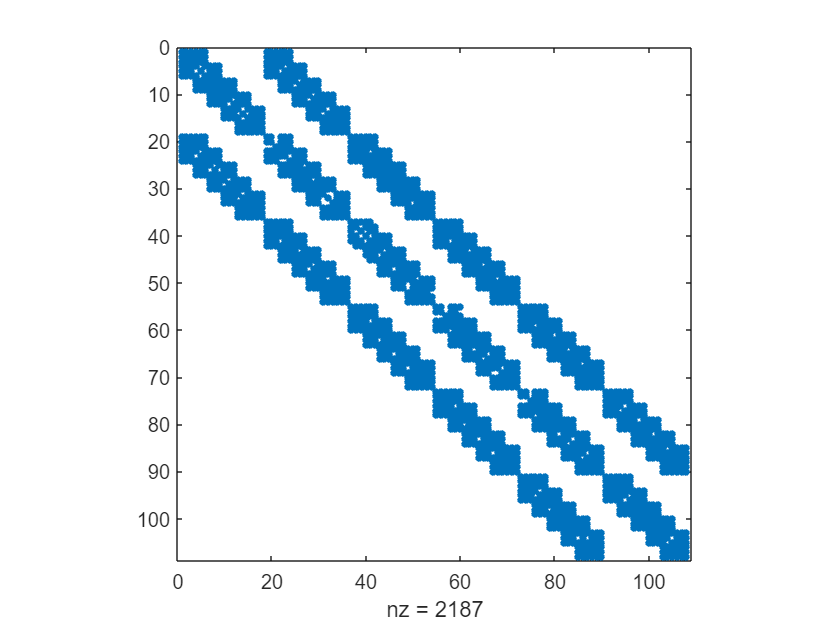

spy(KQ1)

### Nine-noded biquadratic Reissner-Mindlin elements

computeStiffMatrixandForceVectorQ2 = ...
    @computeElementStiffMatrixandForceVectorReissnerMindlinPlate;
computeBasisFunctionsAndDerivsQ2 = ...
    @computeBiquadraticBasisFunctionsAndFirstDerivatives;
[KQ2, FQ2] = ...
    computeMasterStiffMatrixandForceVectorReissnerMindlinPlate ...
    (mshQ2, computeBasisFunctionsAndDerivsQ2, ...
    computeStiffMatrixandForceVectorQ2, propStr);

Sparsity of the master global stiffness matrix

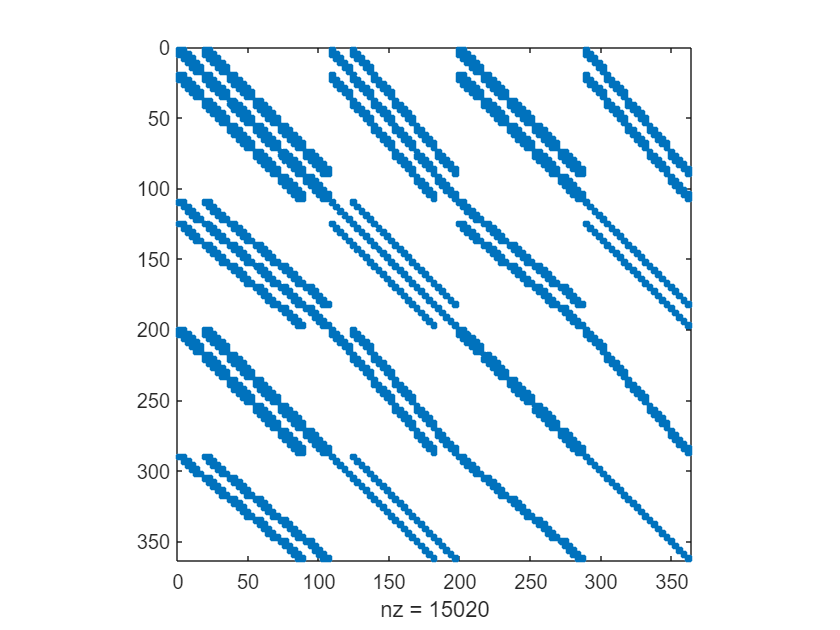

spy(KQ2)

####  **Reflect**

Why is the sparsity pattern of the master stiffness matrix not aligned around the main-diagonal for the case of the biquadratic quadrilateral elements as compared to the bilinear quadrilateral elements?

### Four-noded bilinear Reissner-Mindlin elements with Assumed Natural Strain (ANS)

computeStiffMatrixandForceVector_Q1_ANS = ...
    @computeElementStiffMatrixandForceVectorReissnerMindlinPlateANS;
computeBasisFunctionsAndDerivs_Q1_ANS = ...
    @computeBilinearBasisFunctionsAndFirstDerivatives;
[K_Q1_ANS, F_Q1_ANS] = ...
    computeMasterStiffMatrixandForceVectorReissnerMindlinPlate ...
    (mshQ1, computeBasisFunctionsAndDerivs_Q1_ANS, ...
    computeStiffMatrixandForceVector_Q1_ANS, propStr);

Sparsity of the master global stiffness matrix

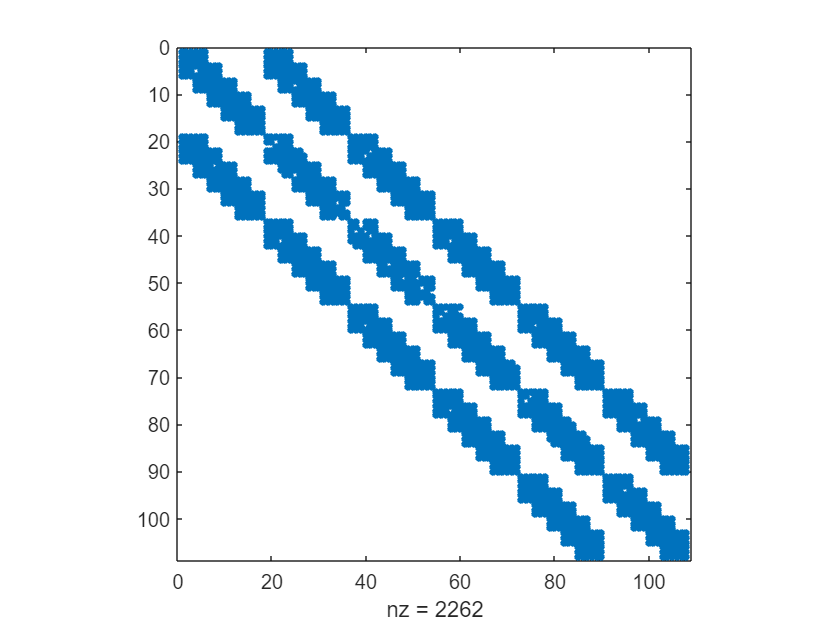

spy(K_Q1_ANS)

## Solution of the Reissner-Mindlin plate problem

### Four-noded bilinear elements

#### Solution of the linear equation system

uQ1 = zeros(numDOFsQ1, 1);
uQ1(freeDOFsQ1, 1) = KQ1(freeDOFsQ1, freeDOFsQ1)\FQ1(freeDOFsQ1);

#### Visualization of the solution in terms of the vertical displacement field

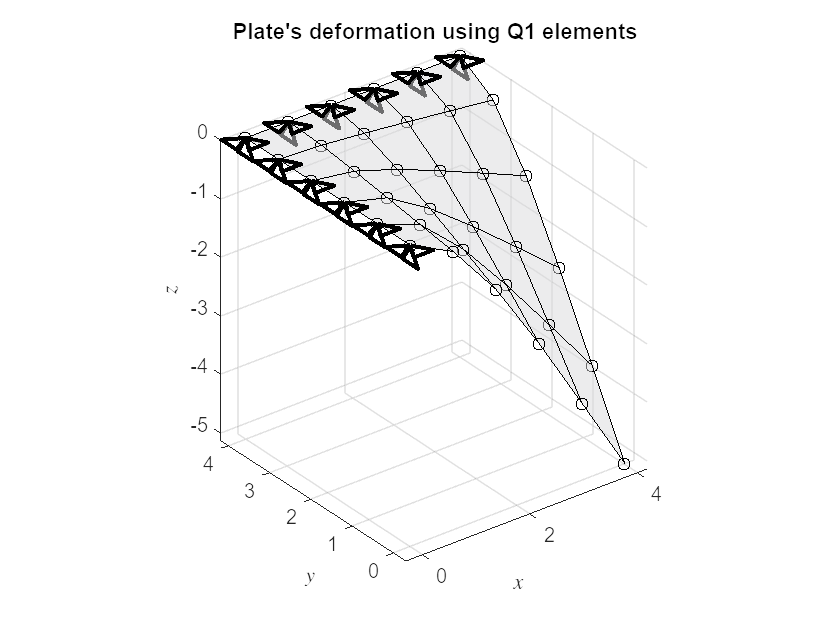

mshCurrQ1 = mshQ1;
scaling = 100;
mshCurrQ1.nodes(:, 3) = mshCurrQ1.nodes(:, 3) + ...
    scaling*uQ1(1:3:end, 1);
numVertices = numel(mshQ1.nodes(:, 1));
plotMesh2d(mshCurrQ1, numVertices, false);
hold on;
scalVer = 1;
[xsQ1, ysQ1, zsQ1] = createSupports3D(mshCurrQ1.nodes, homDOFsQ1, scalVer);
for k = 1:length(xsQ1(:, 1))
    plot3(xsQ1(k, :), ysQ1(k, :), zsQ1(k, :), 'Linewidth', 2, ...
        'Color', 'black');
end
hold off;
axis equal;
xlabel("$x$", "Interpreter","latex")
ylabel("$y$", "Interpreter","latex")
zlabel("$z$", "Interpreter","latex")
title("Plate's deformation using Q1 elements")

#### Visualization of the solution in terms of the rotational field

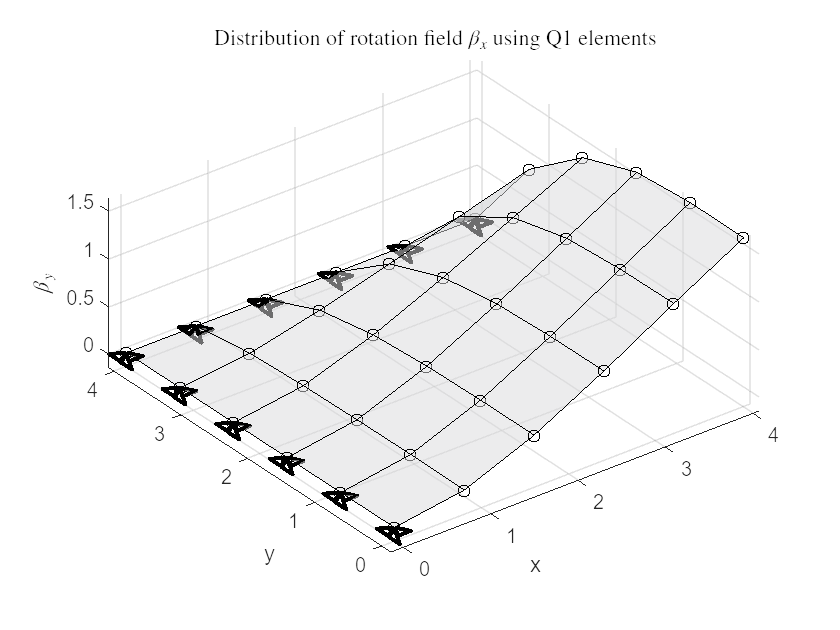

mshCurrQ1Betay = mshQ1;
scaling = 100;
mshCurrQ1Betay.nodes(:, 3) = mshCurrQ1Betay.nodes(:, 3) + ...
    scaling*uQ1(2:3:end);
numVertices = numel(mshQ1.nodes(:, 1));
plotMesh2d(mshCurrQ1Betay, numVertices, false);
hold on;
scalVer = 1;
[xsQ1, ysQ1, zsQ1] = createSupports3D(mshCurrQ1Betay.nodes, homDOFsQ1, scalVer);
for k = 1:length(xsQ1(:, 1))
    plot3(xsQ1(k, :), ysQ1(k, :), zsQ1(k, :), 'Linewidth', 2, ...
        'Color', 'black');
end
hold off;
axis equal;
xlabel("x")
ylabel("y")
zlabel("$\beta_y$", Interpreter="latex")
title("Distribution of rotation field $\beta_x$ using Q1 elements", ...
    Interpreter="latex")

### Nine-noded biquadratic Reissner-Mindlin elements

#### Solution of the linear equation system

uQ2 = zeros(numDOFsQ2, 1);
uQ2(freeDOFsQ2, 1) = KQ2(freeDOFsQ2, freeDOFsQ2)\FQ2(freeDOFsQ2);

#### Visualization of the solution in terms of the vertical displacement field

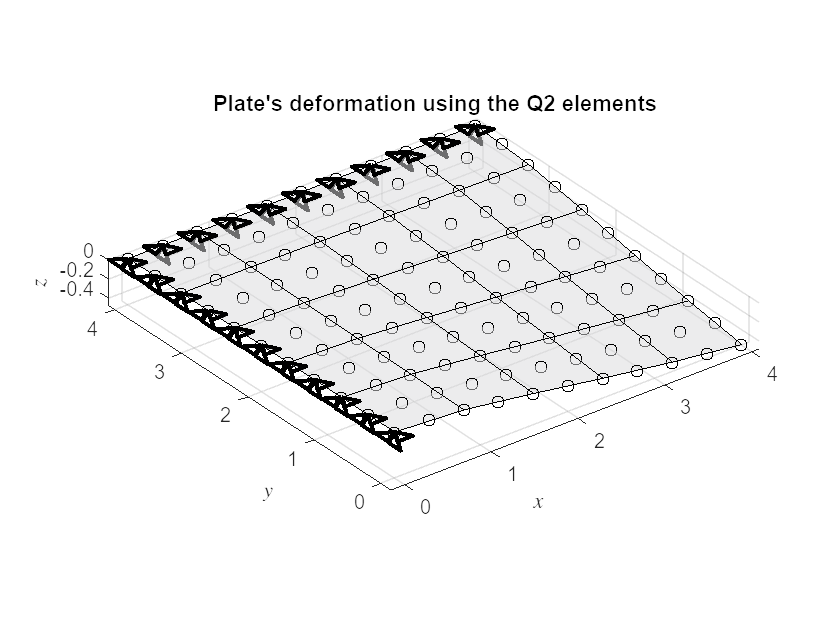

mshCurrQ2 = mshQ2;
scaling = 1;
mshCurrQ2.nodes(:, 3) = mshCurrQ2.nodes(:, 3) + ...
    scaling*uQ2(1:3:end, 1);
numVertices = numel(mshQ1.nodes(:, 1));
plotMesh2d(mshCurrQ2, numVertices, false);
hold on;
scalVer = 1;
[xsQ2, ysQ2, zsQ2] = createSupports3D(mshCurrQ2.nodes, homDOFsQ2, scalVer);
for k = 1:length(xsQ2(:, 1))
    plot3(xsQ2(k, :), ysQ2(k, :), zsQ2(k, :), 'Linewidth', 2, ...
        'Color', 'black');
end
hold off;
axis equal;
xlabel("$x$", "Interpreter", "latex")
ylabel("$y$", "Interpreter", "latex")
zlabel("$z$", "Interpreter", "latex")
title("Plate's deformation using the Q2 elements")

#### Visualization of the solution in terms of the rotational field

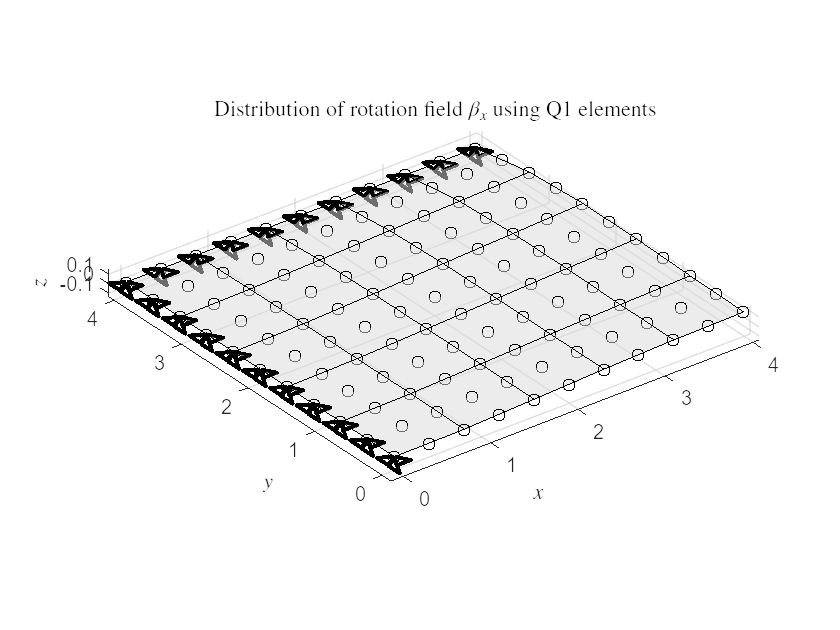

mshCurrQ2Betay = mshQ2;
scaling = 1;
mshCurrQ2Betay.nodes(:, 3) = mshCurrQ2Betay.nodes(:, 3) + ...
    scaling*uQ2(2:3:end, 1);
numVertices = numel(mshQ1.nodes(:, 1));
plotMesh2d(mshCurrQ2Betay, numVertices, false);
hold on;
scalVer = 1;
[xsQ2, ysQ2, zsQ2] = createSupports3D(mshCurrQ2Betay.nodes, homDOFsQ2, scalVer);
for k = 1:length(xsQ2(:, 1))
    plot3(xsQ2(k, :), ysQ2(k, :), zsQ2(k, :), 'Linewidth', 2, ...
        'Color', 'black');
end
hold off;
axis equal;
xlabel("$x$", "Interpreter", "latex")
ylabel("$y$", "Interpreter", "latex")
zlabel("$z$", "Interpreter", "latex")
title("Distribution of rotation field $\beta_x$ using Q1 elements", ...
    Interpreter="latex")

### Four-noded bilinear Reissner-Mindlin elements with Assumed Natural Strain (ANS)

#### Solution of the linear equation system

uQ1ANS = zeros(numDOFsQ1, 1);
uQ1ANS(freeDOFsQ1, 1) = ...
    K_Q1_ANS(freeDOFsQ1, freeDOFsQ1)\F_Q1_ANS(freeDOFsQ1);

#### Visualization of the solution in terms of the vertical displacement field

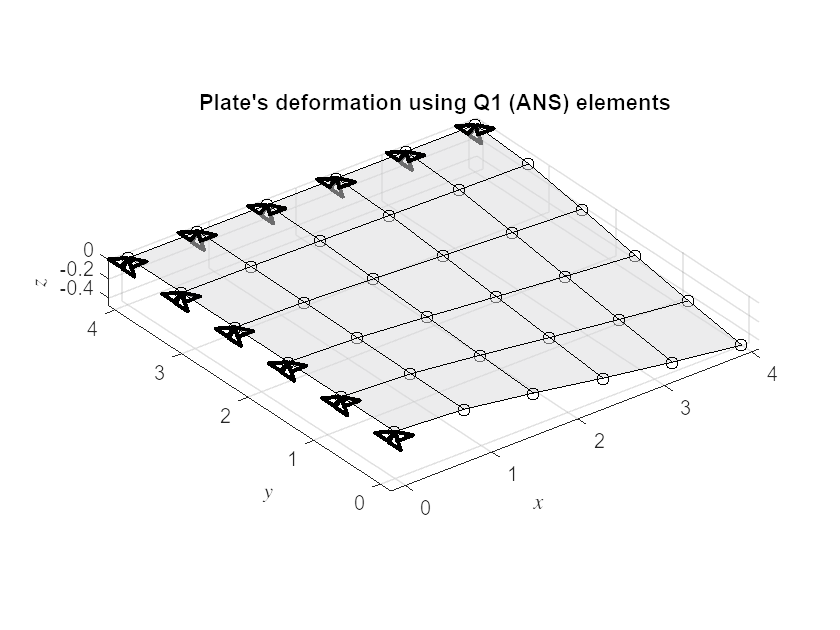

mshCurrQ1ANS = mshQ1;
scaling = 1;
mshCurrQ1ANS.nodes(:, 3) = mshCurrQ1ANS.nodes(:, 3) + ...
    scaling*uQ1ANS(1:3:end, 1);
numVertices = numel(mshQ1.nodes(:, 1));
plotMesh2d(mshCurrQ1ANS, numVertices, false);
hold on;
scalVer = 1;
[xsQ1ANS, ysQ1ANS, zsQ1ANS] = ...
    createSupports3D(mshCurrQ1ANS.nodes, homDOFsQ1, scalVer);
for k = 1:length(xsQ1(:, 1))
    plot3(xsQ1ANS(k, :), ysQ1ANS(k, :), zsQ1ANS(k, :), 'Linewidth', 2, ...
        'Color', 'black');
end
hold off;
axis equal;
xlabel("$x$", "Interpreter","latex")
ylabel("$y$", "Interpreter","latex")
zlabel("$z$", "Interpreter","latex")
title("Plate's deformation using Q1 (ANS) elements")

#### Visualization of the solution in terms of the rotational field

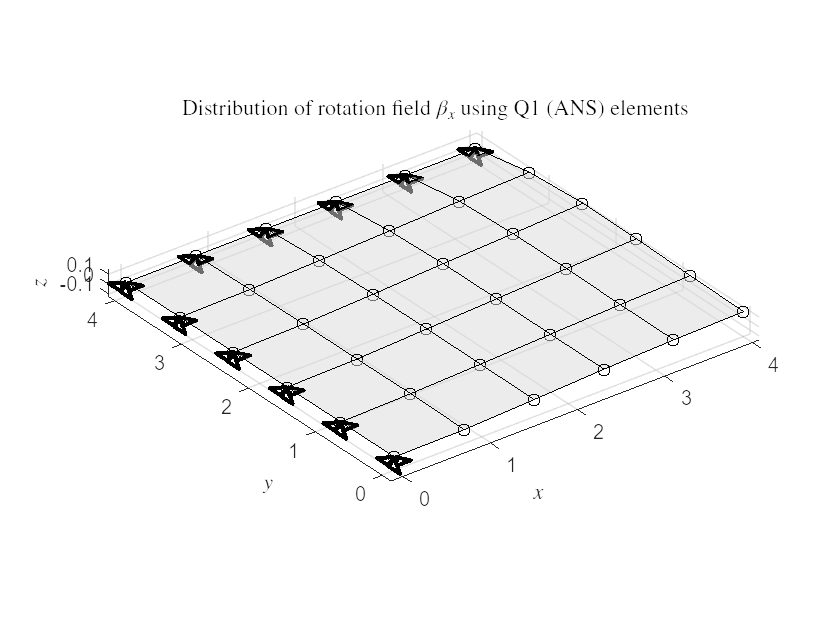

mshCurrQ1ANSBetay = mshQ1;
scaling = 1;
mshCurrQ1ANSBetay.nodes(:, 3) = mshCurrQ1ANSBetay.nodes(:, 3) + ...
    scaling*uQ1ANS(2:3:end, 1);
numVertices = numel(mshQ1.nodes(:, 1));
plotMesh2d(mshCurrQ1ANSBetay, numVertices, false);
hold on;
scalVer = 1;
[xsQ1ANS, ysQ1ANS, zsQ1ANS] = ... 
    createSupports3D(mshCurrQ1ANSBetay.nodes, homDOFsQ1, scalVer);
for k = 1:length(xsQ1(:, 1))
    plot3(xsQ1ANS(k, :), ysQ1ANS(k, :), zsQ1ANS(k, :), 'Linewidth', 2, ...
        'Color', 'black');
end
hold off;
axis equal;
xlabel("$x$", "Interpreter","latex")
ylabel("$y$", "Interpreter","latex")
zlabel("$z$", "Interpreter","latex")
title("Distribution of rotation field $\beta_x$ using Q1 (ANS) elements", ...
    Interpreter="latex")

## Transverse-shear locking due incompatible discretization spaces

The transverse-shear locking can be attributed to the incompatibility of the discretization space for the vertical displacement and rotation fields. This manifests as residual transverse-shear forces for thin plates which trigger this numerical artifact. More information on this topic you can find [here](matlab:open('..\4_TransverseShearLocking_TimoshenkoBeam\main_Chapter4_TransverseShearLocking_TimoshenkoBeam.mlx')) based on the Timoshenko beam problem.

In this section the shear forces $q_x = \alpha G t \gamma_x = \alpha G t \overbrace{\left( \frac{\partial w}{\partial X} + \beta_y \right)}^{\gamma_x}$are computed using both the bilinear and the biquadratic elements along the line $Y = 2$ m.

### Number of evaluation points

numPts = 100;

  **Try**

Modify the number of evaluation points by means of variable `numPts`

 **Reflect**

- How do the different distributions of the transverse-shear force change with respect to the number of evaluation points and why?

- How many evaluation points do you need to appropriately describe the different transverse-shear force distributions? Is this value constant or does it depend on the chosen value for the beam's edge size and thickness, $L$ and $t$, respectively?

### Transverse-shear force distribution along the the plate's section

Navigate to [THIS](matlab:open('./main_Chapter41_ReissnerMindlinSquarePlate_ShearForces.mlx')) Live Script for the detailed analysis.

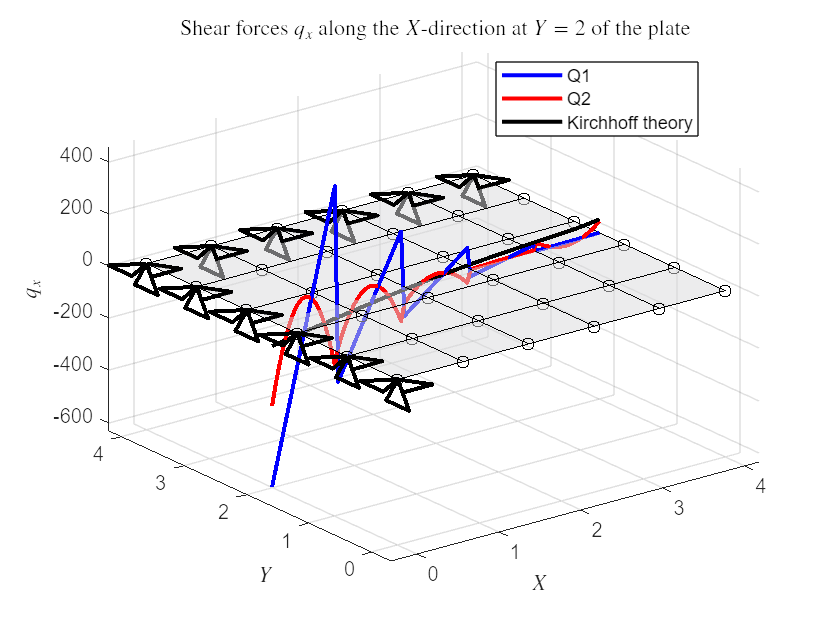

main_Chapter41_ReissnerMindlinSquarePlate_ShearForces

## Slenderness study on transverse shear-locking

In this section it is investigated the behavior of the convergence as the slenderness (length over thickness) goes to infinity $L/t \rightarrow \infty$, namely, as the thickness goes to zero $t \rightarrow 0$. As the thickness goes to zero, the spurious forces due to transverse shear locking increase, leading to an ever increasing artificially stiffening behavior. To keep the solution constant the same scaling factor is applied both to the applied force and the thickness, so that the ratio $p/t$, and thus the resulting deformation, remains constant.

### Bounding exponents of ten

The space of the slenderness ratio is defined by means of power of ten, namely, $\lambda \in \left[ \begin{array}{cc} 10^{\text{\texttt{mPowL}}}, 10^{\text{\texttt{mPowU}}} \end{array} \right]$

mPowL = -2;
mPowU = 4;
if floor(mPowL) ~= mPowL || floor(mPowU) ~= mPowU
    error("Variables 'mPowL' and 'mPowU' must be integers")
end
if mPowL >= mPowU
    error("Integer 'mPowL' must be strictly smaller than integer 'mPowU'")
end

  **Try**

Modify the bounding values of the slenderness $\lambda $ by means of variables `mPowL` and `mPowU`

 **Reflect**

How does the slenderness space affect the slenderness graph below and why?

### Slenderness study

Navigate to [THIS](matlab:open('./main_Chapter42_ReissnerMindlinSquarePlate_SlendernessStudy.mlx')) Section for the detailed analysis.

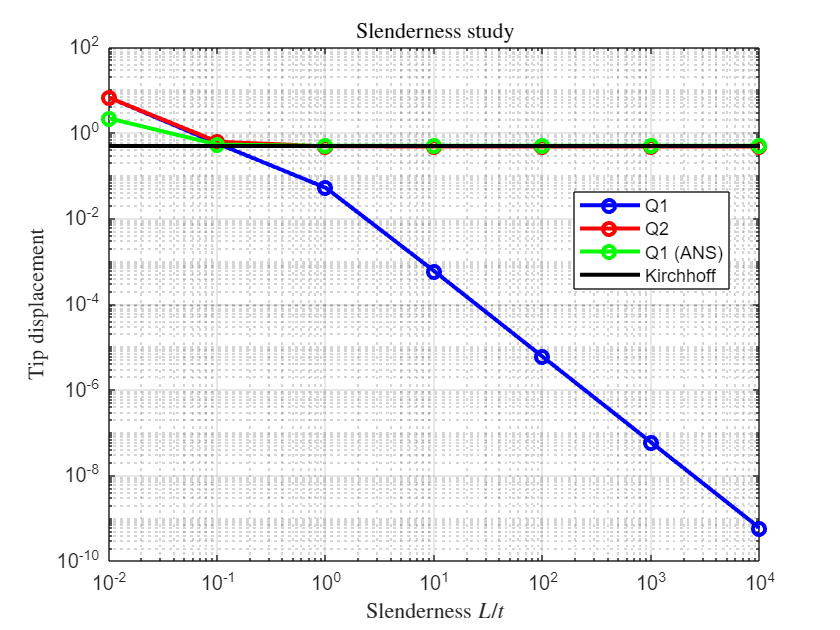

main_Chapter42_ReissnerMindlinSquarePlate_SlendernessStudy

## Convergence study on transverse shear-locking

Another way to identify transverse shear locking is to perform a convergence study for different slenderness levels of the structure. A reduced convergence rate as the slenderness level increases indicates the presence of transverse shear-locking. In extreme transverse shear-locking cases the convergence rate drops to nearly zero

### Number of refinement levels

numRef = 17;
if floor(numRef) ~= numRef
    error("Variables 'numRef' must be an integer")
end
if numRef <= 0
    error("Variable 'numRef' must be strictly positive")
end

  **Try**

Modify the number of refinment levels using variable `numRef` for different slenderness values $\lambda$

 **Reflect**

How is the convergence rate affected by the different slenderness values $\lambda$?

### Expected solution in terms of the Kirchhoff plate theory

wKirchhoff = 0.487463124419606;

### Point of interest for the computation of the displacement

xyPostProc = [XLx 0];

### Convergence study based on the tip plate's displacement

Navigate to [THIS](matlab:open('./main_Chapter43_ReissnerMindlinSquarePlate_ConvergenceStudy.mlx')) section for the detailed analysis.

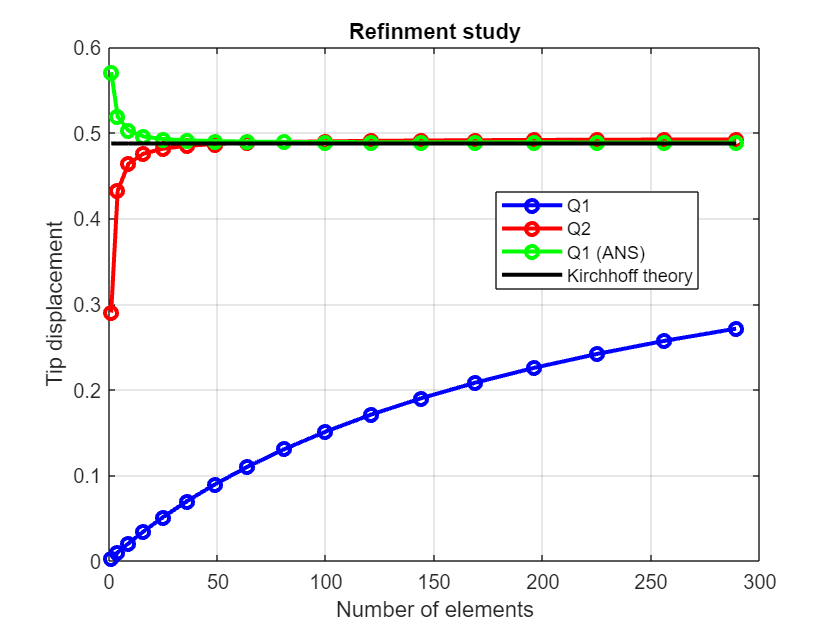

main_Chapter43_ReissnerMindlinSquarePlate_ConvergenceStudy

## References

[[1] Hughes, Thomas JR. *The finite element method: linear static and dynamic finite element analysis*. Courier Corporation, 2012.](https://doi.org/10.1111/j.1467-8667.1989.tb00025.x)

[](https://doi.org/10.1007/978-3-540-78319-0)[[2] Brezzi, F., Boffi, D., Demkowicz, L., Durán, R. G., Falk, R. S., & Fortin, M. (2008). Mixed finite elements, compatibility conditions, and applications. *Springer*, *2*, 4-2.](https://doi.org/10.1007/978-3-540-78319-0)